# Calibration of ISR Raw Voltages

**Converting raw signal and noise to **$P_{r\text{ }}$** in Watts**


$$P_r =P_{\mathrm{cal}} \times \frac{\left(\mathrm{Signal}-\mathrm{Noise}\right)}{\left(\mathrm{Cal}-\mathrm{Noise}\right)}\text{ }\mathrm{Watts}$$


Initilization

clear variables;

nPulsesIntegrated = 256;
C=define_universal_constants;

ksysFile = 'G:\Team Drives\Semeter-Research in Progress\pfisr20180326.006\Calibration\cal-201803-calibration-ksys-04.02.2018.txt';
beamCalibration = dlmread(ksysFile); % Beamcode, Az, El, Ksys


Loading the H5File

% h5FileStr='G:\Team Drives\Semeter-Research in Progress\pfisr20140425\20140425.001\d0394107.dt0.h5';
h5FileStr='G:\Team Drives\Semeter-Research in Progress\pfisr20180326.006\d0199786.dt0.h5';
h5DataLoc = '/Raw11/Raw/Samples/Data';
raw.data = h5read(h5FileStr,h5DataLoc);
h5DataLoc = '/Raw11/Raw/RadacHeader/BeamCode';
raw.beamCode=h5read(h5FileStr,h5DataLoc);
h5DataLoc = '/Raw11/Raw/RadacHeader/RadacTime';
raw.time = unix_to_matlab_time(h5read(h5FileStr,h5DataLoc));


Integrating (and averaging) signal across nPulsesIntegrated

signal = abs(decoding(raw.data)).^2;  % Default over-sampled barker code
[signal,uniqueBeamCodes,time] = reshape_beam_wise(signal,raw.beamCode,raw.time); % Reshaping signal beam-wise
[integratedSignal,outputTime]=integrate_pulses(signal,time,nPulsesIntegrated);
averageSignal = integratedSignal./nPulsesIntegrated;
time = min(outputTime.min,[],2);
nSamples = size(integratedSignal,3);
nBeams = size(integratedSignal,2);
nTimeRecords  = size(integratedSignal,1);

Estimating noise from the HDF5 files

% Loading Noise & Averaging it across ranges
h5DataLoc = '/CohCode/Noise/Power/Data';
noise = double(h5read(h5FileStr,h5DataLoc));
noise = squeeze(mean(noise,1))';
noisePulsesIntegrated = double(h5read(h5FileStr,'/CohCode/Noise/PulsesIntegrated'))';
noise = repmat(noise,1,1,nSamples)./noisePulsesIntegrated;

% Loading Cal & Averaging it across ranges
h5DataLoc = '/CohCode/Cal/Power/Data';
cal = double(h5read(h5FileStr,h5DataLoc));
cal = squeeze(mean(cal,1))';
calPulsesIntegrated = double(h5read(h5FileStr,'/CohCode/Cal/PulsesIntegrated'))';
cal = repmat(cal,1,1,nSamples)./calPulsesIntegrated;


Absolute calibration power in watts


$$P_{\mathrm{cal}} =k_B T_{\mathrm{cal}} B$$


h5DataLoc = '/Rx/Bandwidth';
B = h5read(h5FileStr,h5DataLoc);
h5DataLoc = '/Rx/CalTemp';
Tcal = h5read(h5FileStr,h5DataLoc);
Pcal = C.kb*Tcal*B;


Received power in watts

powerReceivedTotal = Pcal*(integratedSignal-noise).*(cal-noise).^-1; % Received power in watts
powerReceived = Pcal*(averageSignal-noise).*(cal-noise).^-1; % Received power in watts
SNR = (averageSignal-noise).*(noise).^-1;

**Electron density**

pulseLength=h5read(h5FileStr,'/Raw11/Raw/Pulsewidth');
powerTransmitted = repmat(mean(h5read(h5FileStr,'/Tx/Power'),1)',1,nBeams,nSamples); %Matrix
raw.range = h5read(h5FileStr,'/Raw11/Raw/Power/Range');  
frequency = h5read(h5FileStr,'/Tx/Frequency');
site.lat = h5read(h5FileStr,'/Site/Latitude');
site.lon = h5read(h5FileStr,'/Site/Longitude');
site.alt = h5read(h5FileStr,'/Site/Altitude');

range = raw.range(1:nSamples);
rangeMatrix = permute(repmat(range,1,nBeams,nTimeRecords),[3 2 1]);

frequencyMatrix = repmat(mean(frequency,1)',1,nBeams,nSamples);

k = 2*pi*frequencyMatrix./C.c;% wave vector


Finding Ksys

for i=1:1:nBeams
    Ksys(1,i,1) = beamCalibration(beamCalibration(:,1)==uniqueBeamCodes(i),4); %need to find it
    az(1,i,1) = beamCalibration(beamCalibration(:,1)==uniqueBeamCodes(i),2);
    el(1,i,1) = beamCalibration(beamCalibration(:,1)==uniqueBeamCodes(i),3);
end
Ksys = repmat(Ksys,nTimeRecords,1,nSamples);
azimuth = repmat(az,nTimeRecords,1,nSamples);
elevation = repmat(el,nTimeRecords,1,nSamples);

Finding altitude of data points for MSIS

[latitude,longitude,altitude]=aer2geodetic(azimuth,elevation,rangeMatrix,site.lat,site.lon,site.alt,wgs84Ellipsoid('m')); %default in degrees

Calculating F10.7A, F10.7 and AP values during March 2018

Using 28 Mar 2017, since data is not yet available for 28 Mar 2018

timeaph = datenum(datevec(time(1)-365));
% timeaph = datenum('26 Mar 2017');
[F107A, F107, APH] = f107_aph(timeaph); % Since 26 Mar 2018 data is unavailable currently (8th April 2018)

Calculating neutral temperature from MSIS

altMSIS=squeeze(altitude(1,:,:))/1000; altMSIS(altMSIS<0)=0; %km
latMSIS = squeeze(latitude(1,:,:));
lonMSIS = squeeze(longitude(1,:,:));
timeMSIS =repmat(timeaph,1,nBeams*nSamples);
msis00Data = onera_desp_lib_msis('nrlmsise00',timeMSIS,[altMSIS(:),latMSIS(:),lonMSIS(:)],0,repmat(F107A,nBeams*nSamples,1),repmat(F107,nBeams*nSamples,1),repmat(APH,nBeams*nSamples,1));
Tn=reshape(msis00Data.AltTemp,nBeams,nSamples);



$$\begin{array}{l}
\mathrm{Since}\text{ }\text{ }\lambda_D =\sqrt{\frac{\left(\epsilon_0 k_B T_{e\text{ }} \right)}{n_e q_e^2 }}\text{ }\mathrm{and}\text{ }P_r =\frac{\text{ }P_t \tau_p }{r^2 }\text{ }K_{\mathrm{sys}} \text{ }\frac{N_e }{\left(1+k^2 \lambda {\text{ }}_D^2 \right)\left(1+k^2 \lambda {\text{ }}_D^2 +T_r \right)}\\
{\alpha \text{ }N}_{e\text{ }}^3 \text{  }-\left(1+T_r \right)N_e^2 \text{ }-\beta \left(2+T_r \right)N_e -\beta^2 =0\text{ }\text{ }\text{ }\mathrm{where}\text{ }\alpha =\frac{P_t \tau_p }{r^2 P_r }K_{\mathrm{sys}} \text{ }\mathrm{and}\text{ }\beta \text{ }=k^2 \frac{\epsilon_0 k_b T_e }{2q_e^2 }
\end{array}$$


Solving the above polynomial, and estimtaing the electron density

Te = permute(repmat(Tn,1,1,nTimeRecords),[3,1,2]); %set Te=Tn
Tr = ones(nTimeRecords,nBeams,nSamples);
a = powerTransmitted.*pulseLength.*Ksys.*(double(rangeMatrix).^-2).*double(powerReceived).^-1;
b =  (k.^2).*(C.epsilon0).*(C.kb).*Te.*(2.*(C.e).^2).^-1;
coefficients=double([a(:),-(1+Tr(:)),-b(:).*(2+Tr(:)),-b(:).^2]);
coeffCell = num2cell(coefficients,2);
Ne_noDebye = double(2.*a.^-1);
r = cellfun(@(x) roots(x),coeffCell,'UniformOutput',false);
[val,indxValidr]=min(abs(cell2mat(r')-repmat(Ne_noDebye(:),1,3)'));
for i=1:1:length(indxValidr)
    validr(i) = r{i}(indxValidr(i));
end
Ne = reshape(validr,nTimeRecords,nBeams,nSamples);

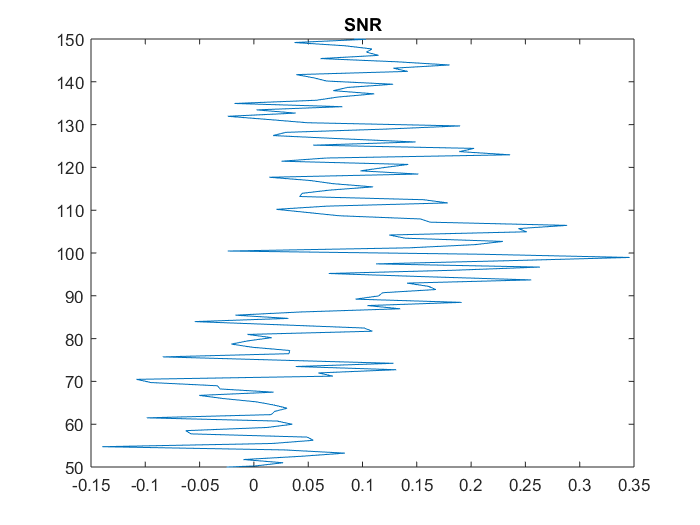

figure;
altRange = [50 150];
SNRdB = 20*log10(SNR);
plot(squeeze(SNR(1,1,:)),altMSIS(1,:));
ylim(altRange);
title('SNR');

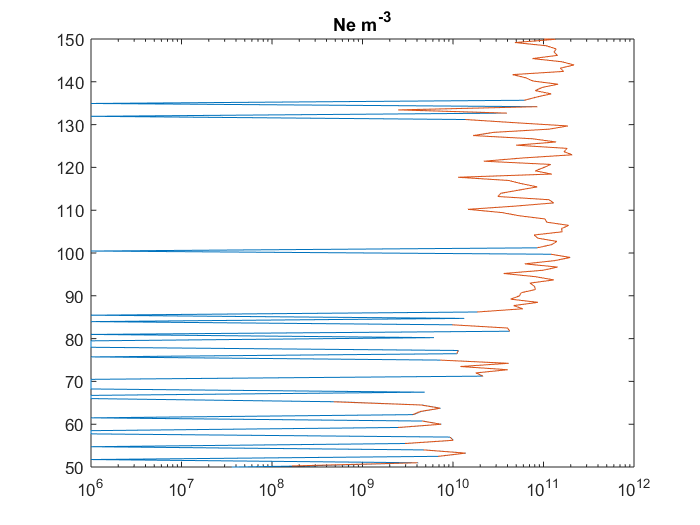

figure;
semilogx(squeeze(Ne(1,1,:)),altMSIS(1,:)); hold on; plot(squeeze(Ne_noDebye(1,1,:)),altMSIS(1,:)); 
ylim(altRange);
title('Ne m^-^3');

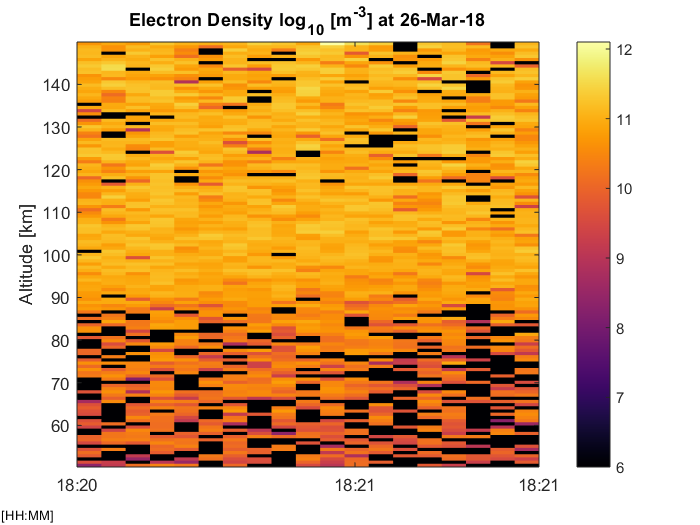

figure;
altMinIndx=find_altitude(altMSIS(1,:),altRange(1));
altMaxIndx=find_altitude(altMSIS(1,:),altRange(2));
altIndx = [altMinIndx:altMaxIndx];
Ne(Ne<10^6)=10^6;
plot_2D_time_series(time',altMSIS(1,altIndx)',log10(real(squeeze(Ne(:,1,altIndx))')),0.5/60,1);
colormap inferno;
colorbar;


$$\begin{array}{l}
P_r -\mathrm{received}\text{ }\mathrm{power}\text{ }\left(\mathrm{Watts}\right)\\
P_t -\mathrm{transmit}\text{ }\mathrm{power}\text{ }\left(\mathrm{Watts}\right)\\
\tau_p -\mathrm{pulse}\text{ }\mathrm{length}\text{ }\left(\mathrm{seconds}\right)\\
r-\mathrm{range}\text{ }\left(\mathrm{meters}\right)\\
N_e -\mathrm{electron}\text{ }\mathrm{density}\text{ }\left(m^{-3\text{ }} \right)\\
k-\mathrm{Bragg}\text{ }\mathrm{scattering}\text{ }\mathrm{wavenumber}\text{ }\left(\mathrm{rad}/m\right)\\
\lambda {\text{ }}_D -\mathrm{Debye}\text{ }\mathrm{length}\text{ }\left(m\right)\\
T_r -\mathrm{electron}\text{ }\mathrm{to}\text{ }\mathrm{ion}\text{ }\mathrm{temperation}\text{ }\mathrm{ratio}\text{ }\left(T_e /T_i \right)\\
K_{\mathrm{sys}} -\mathrm{system}\text{ }\mathrm{constant}\text{ }\left(m^5 /s\right)\\
k_B -\mathrm{Boltzmann}\text{ }\mathrm{constant}\text{ }\left(\text{ }J/\mathrm{kg}\text{ }K\right)\\
T_{\mathrm{cal}\text{ }} -\mathrm{temperature}\text{ }\mathrm{of}\text{ }\mathrm{calibration}\text{ }\mathrm{source}\text{ }\left(K\right)\\
B-\mathrm{receiver}\text{ }\mathrm{bandwidth}\text{ }\left(\mathrm{Hz}\right)\\
\theta {\text{ }}_{\mathrm{BS}} -\mathrm{angle}\text{ }\mathrm{off}\text{ }\mathrm{boresight}\\
A,B-\mathrm{constants}\\
f_{r\text{ }} -\mathrm{plasma}\text{ }\mathrm{line}\text{ }\mathrm{frequency}\text{ }\left(\mathrm{Hz}\right)\\
f_p -\mathrm{plasma}\text{ }\mathrm{frequency}\left(\mathrm{Hz}\right)\\
m_e -\mathrm{electron}\text{ }\mathrm{mass}\text{ }\left(\mathrm{kg}\right)\\
f_c -\mathrm{electron}\text{ }\mathrm{cyclotron}\text{ }\mathrm{frequency}\left(\mathrm{Hz}\right)\\
\alpha -\mathrm{magnetic}\text{ }\mathrm{aspect}\text{ }\mathrm{angle}
\end{array}$$
